# Transfer Learning(GoogLeNet)

**Load Pretrained Network**

clear, clc
net = googlenet;
analyzeNetwork(net)

#### 네트워크 입력 크기 확인 

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


### AIData 폴더의 이미지를 가져오기

imds = imageDatastore('우유','IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain, imdsValidation] = splitEachLabel(imds,0.7,'randomized');

## 이미지 확인

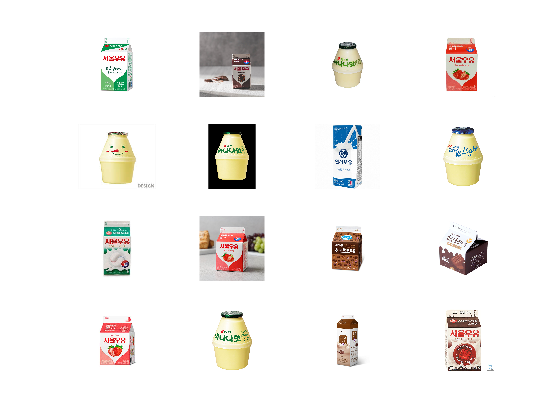

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## 마지막 계층 바꾸기

lgraph = layerGraph(net);

learnableLayer = lgraph.Layers(end-2);
classLayer = lgraph.Layers(end);

numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);   

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

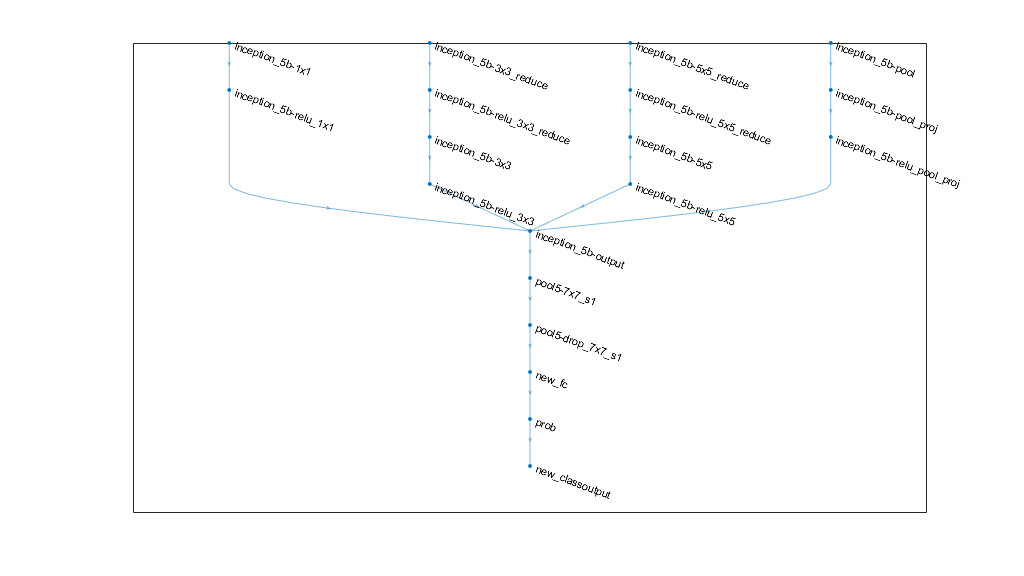

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

#### 훈련 이미지 데이터 증대

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

#### 검증 이미지 데이터 증대

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

## 딥러닝 옵션

miniBatchSize = 10;
valFrequency = floor(numel(imdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',12, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

## 딥러닝 훈련

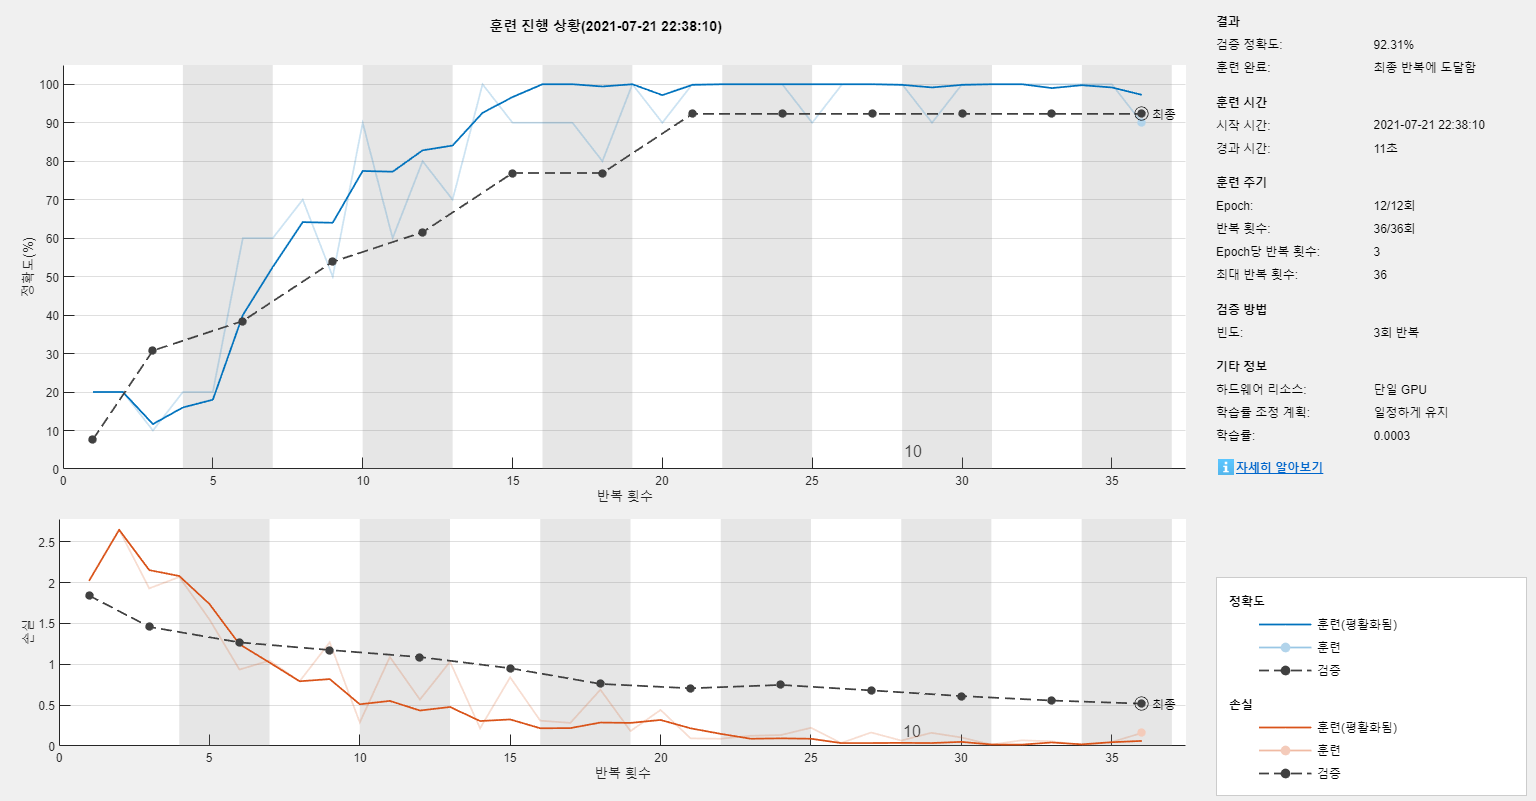

googlenetTransfer = trainNetwork(augimdsTrain,lgraph,options);

save('googlenetTransfer.mat', 'googlenetTransfer')
%load('googlenetTransfer.mat', 'googlenetTransfer')

### 딥러닝 검증

[YPred,probs] = classify(googlenetTransfer,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9231

#### 딥러닝 검증

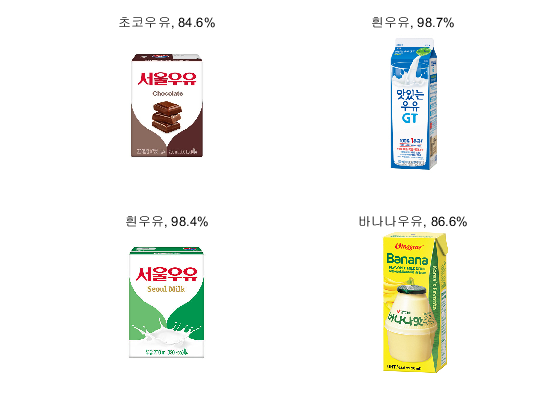

idx = randperm(numel(augimdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

# 웹캠 실시간

cam = webcam;

훈련한 네트워크(딥러닝) 불러오기

load("googlenetTransfer.mat","googlenetTransfer")

웹캠으로 우유 딥러닝 확인하기 (이미지 1장)

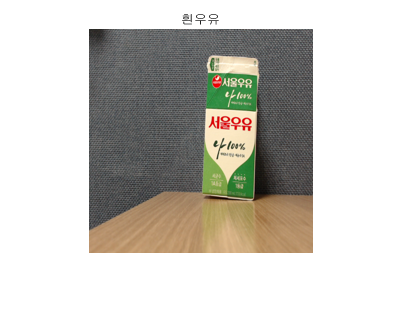

img = snapshot(cam);
img = imresize(img, [224 224]);
label = classify(googlenetTransfer, img);

figure,
imshow(img)
title(label);

실시간으로 딥러닝 실행하기 (이미지 및 바 그래프 표시)

※ 아래 코드를 복사해서 m파일에서 실행해야 한다.

while 1
    img = snapshot(cam);
    img = imresize(img, [224 224]);
    [label, scores] = classify(googlenetTransfer,img);
    
    [~, idx] = sort(scores,'descend');
    idx = idx(4:-1:1);
    classNamesTop = netTransfer.Layers(end).Classes(idx);
    scoresTop = scores(idx);
    
    figure(1),
    subplot(121), imshow(img)
    title(label);
    subplot(122), barh(scoresTop)
    xlim([0 1]);
    title('Top 4 Predictions')
    xlabel('Probability')
    yticklabels(classNamesTop)    
    drawnow;
end
